%Define system
clc
clear
A = [1.2 1; 0 1];
B = [0; 1];
x0 = [2; 0];

model = LTISystem('A', A, 'B', B);
model.x.min = [-15; -15];
model.x.max = [15; 15];
model.u.min = -1;
model.u.max = 1;

%part a

X = Polyhedron('lb', model.x.min, 'ub', model.x.max);
U = Polyhedron('lb', model.u.min, 'ub', model.u.max);

% Define cost function
Q = eye(2); 
R = 100;

model.x.penalty = QuadFunction(Q);
model.u.penalty = QuadFunction(R);

%% Define terminal constraint and penalty
Xf = zeros(2, 1);
Tset = Polyhedron('Ae', eye(2), 'be', Xf);
model.x.with('terminalSet');
model.x.terminalSet = Tset;

PN = model.LQRPenalty;
Pf = PN.weight;
disp('Terminal weight Pf')

Terminal weight Pf


disp(Pf)

   16.0929   32.9899
   32.9899   93.9396



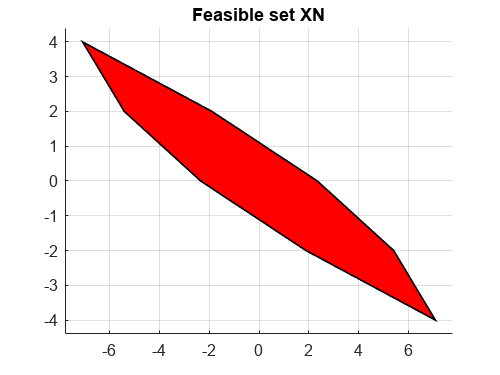

model.x.with('terminalPenalty');
model.x.terminalPenalty = PN;

% Compute reachable set
N = 4;
XN = pre_operation(model, Tset, N);

% Visualize reachable set
fig1 = figure('Name', 'Feasible set XN', 'Color', 'white');
set(fig1, 'Units', 'Pixels', 'Position', [0 0 400 300]);
plot(XN);
title('Feasible set XN');

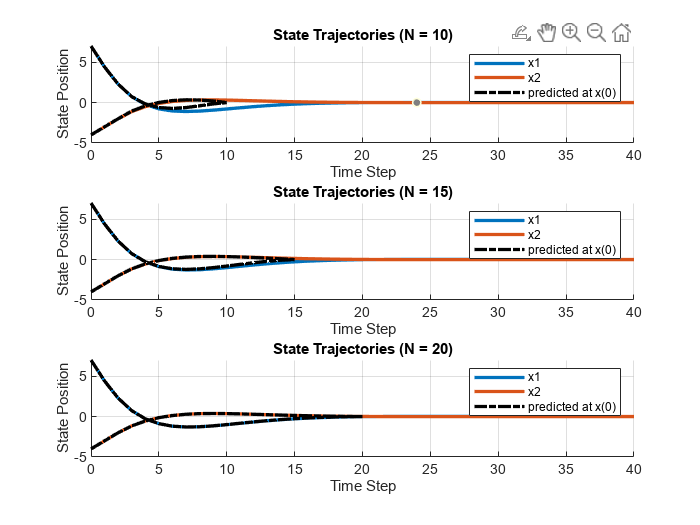


% partb
Np = 20;
N_values = [10, 15, 20];
% Define the initial state
x0 = [7; -4];
% Set the number of simulation steps
Nsim = 40;
% Set the initial value of N to 1
N = 1;
% Create the MPC controller
mpc = MPCController(model, N);
% Create the closed loop system
loop = ClosedLoop(mpc, model);

% Define the list of N values to simulate
N_values = [10, 15, 20];

fig = figure('Name', 'MPC Controller', 'Color', 'white');

% Loop through each value of N
for i=1:numel(N_values)
    % Update the MPC controller with the current value of N
    mpc.N = N_values(i);
    % Simulate the closed loop system with the updated MPC controller
    datasim = loop.simulate(x0,Nsim);
    % Evaluate the open loop system with the updated MPC controller
    [~, ~, openloop] = mpc.evaluate(x0);
    % Store the results of the open loop simulation in a cell array
    mpceval = openloop;

    % Create the subplot for the predicted vs actual state trajectories
    subplot(3, 1, i);
    hold on, grid on;
    plot(0:Nsim, datasim.X', 'Linewidth',2);
    plot(0:N_values(i), mpceval.X', '-.', 'Linewidth',2, 'Color','black');
    title(sprintf('State Trajectories (N = %d)', N_values(i)));
    xlim([0 Nsim]);
    xlabel('Time Step');
    ylabel('State Position');
    legend({'x1','x2','predicted at x(0)'});


end




% part c
% Define constraints
X = Polyhedron('lb', model.x.min, 'ub', model.x.max);
U = Polyhedron('lb', model.u.min, 'ub', model.u.max);

% Define cost function
Q = eye(2);
R = 100;
model.x.penalty = QuadFunction(Q);
model.u.penalty = QuadFunction(R);

% Define terminal constraint and penalty
Xf = 0.01 * ones(2, 1);
Tset = Polyhedron('Ae', eye(2), 'be', Xf);
PN = model.LQRPenalty;
Pf = PN.weight;
model.x.with('terminalPenalty');

model.x.terminalPenalty = PN;
model.x.with('terminalSet');

model.x.terminalSet = Tset;

% Define MPC controller
N = 20;
mpc = MPCController(model, N);

% Compute explicit MPC solution
expmpc = mpc.toExplicit();

mpt_plcp: 25 regions


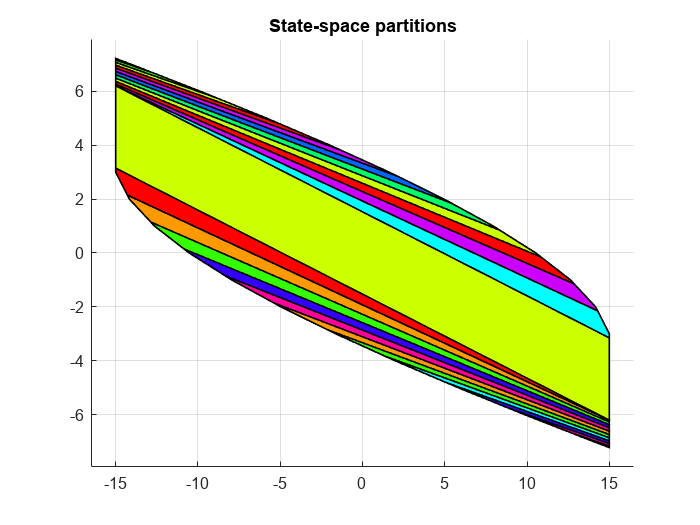


% Plot state-space partitions
figure;
expmpc.partition.plot;
title('State-space partitions');



% part d
% Obtain the invariant set of the system
C_inf = model.invariantSet();

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...
Iteration 9...
Iteration 10...
Iteration 11...
Iteration 12...


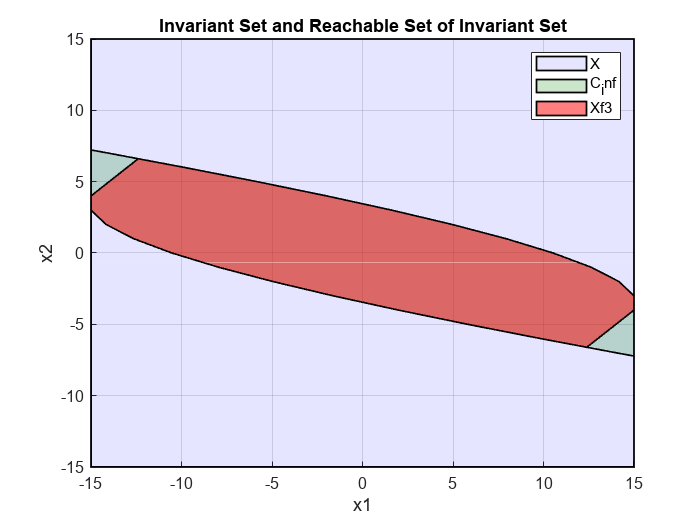


% Obtain the reachable set of the invariant set
Xf3 = model.reachableSet('X', C_inf, 'U', U, 'N', 1, 'direction', 'forward');
Xf3 = Xf3.intersect(C_inf);

% Visualize the sets
figure('Color', 'white');
hold on;
grid on;

plot(X, 'alpha', 0.1, 'Color', 'blue'); % Plot the state constraints
plot(C_inf, 'alpha', 0.2, 'Color', 'green'); % Plot the invariant set
plot(Xf3, 'alpha', 0.5, 'Color', 'red'); % Plot the reachable set of the invariant set

% Set the legend
legend({'X','C_inf','Xf3'});

% Set the labels
xlabel('x1');
ylabel('x2');

% Set the title
title('Invariant Set and Reachable Set of Invariant Set');

% Set the axis limits
xlim([-15, 15]);
ylim([-15, 15]);